# **unsteady-state Flux Balance Analysis (uFBA)**

## **James T. Yurkovich**

Department of Bioengineering and the Bioinformatics and Systems Biology Program, University of California, San Diego USA

Reviewed by Aarash Bordbar

## INTRODUCTION

In this tutorial, we will use unsteady-state Flux Balance Analysis (uFBA) [1] to integrate exo- and endo-metabolomics data [2] into a constraint-based metabolic model for the human red blood cell [3]. The uFBA method allows for bypassing the steady-state assumption for intracellular metabolites that are measured. 

We can model the flux through a metabolic network using a set of linear equations defined by


$$\mathbf{S}\cdot \mathbf{v}=\mathbf{b}$$


where **S** is the stoichiometric matrix, **v** is a vector of fluxes through the chemical reactions defined in **S**, and **b** represents constraints on the change of metabolite concentrations; at steady-state, **b **= 0. If the metabolomics measurements are non-linear (i.e., Fig. 1), then the first step of the uFBA workflow is to identify discrete time intervals which represent linearized metabolic states (Fig. 1). Once discrete states are identified (the raw data if linear), we proceed to estimating metabolite concentration rates of change. For each metabolic state, we can use linear regression to calculate the rate of change of each metabolite concentration. If the rate of change is significant, the model is updated by changing the steady-state constraint from 0 to 


$$\begin{array}{l}
\mathbf{S}\cdot \mathbf{v}\text{ }\ge {\mathbf{b}}_1 \\
\mathbf{S}\cdot \mathbf{v}\text{ }\le {\mathbf{b}}_2 
\end{array}$$


where [$\mathbf{b}_1$, $\mathbf{b}_2$] represents the 95% confidence interval for each significantly changing metabolite. All unmeasured metabolites are assumed to be at steady-state (i.e., $\mathbf{b}_1 = \mathbf{b}_2 = 0$).

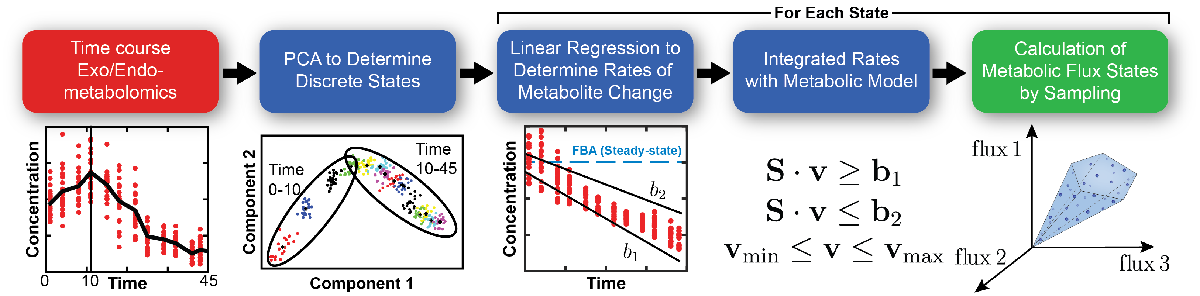

                                                    Fig. 1 | Overview of the uFBA workflow.

## MATERIALS

## Equipment Setup

Running uFBA requires the installation of a mixed-integer linear programming solver. We have used Gurobi 7.0.0 (http://www.gurobi.com/downloads/download-center) which is freely available for academic use (this workflow has only been tested with Gurobi solvers; use other solvers at your own risk). This tutorial uses the Statistics Toolbox to perform linear regression (if the Statistics Toolbox is not installed, compute linear regression manually; see `testUFBA.m`).

## PROCEDURE 

## Initialize

Running uFBA requires the use of several functions from the COBRA Toolbox.

initCobraToolbox



      _____   _____   _____   _____     _____     |
     /  ___| /  _  \ |  _  \ |  _  \   / ___ \    |   COnstraint-Based Reconstruction and Analysis
     | |     | | | | | |_| | | |_| |  | |___| |   |   The COBRA Toolbox - 2017
     | |     | | | | |  _  { |  _  /  |  ___  |   |
     | |___  | |_| | | |_| | | | \ \  | |   | |   |   Documentation:
     \_____| \_____/ |_____/ |_|  \_\ |_|   |_|   |   <a href="http://opencobra.github.io/cobratoolbox">http://opencobra.github.io/cobratoolbox</a>
                                                  | 

 > Checking if git is installed ...  Done.
 > Checking if the repository is tracked using git ...  Done.
 > Checking if curl is installed ...  Done.
 > Checking if remote can be reached ...  Done.
 > Initializing and updating submodules ... Done.
 > Adding all the files of The COBRA Toolbox ...  Done.
 > Define CB map output... set to svg.
 > Retrieving models ...   Done.
 > TranslateSBML is installed and working properly.
 > Configuring sol

We first load in sample data. This data is absolutely quantified and has already been volume adjusted such that intracellular and extracellular metabolite concentrations have compatible units. 

global CBTDIR
load([CBTDIR filesep 'tutorials' filesep 'uFBA' filesep 'sample_data.mat']);

The `sample_data.mat` file contains the following variabels:

- `met_data`: a matrix containing the exo- and endo-metabolomics data

- `met_IDs`: a cell array containing the BiGG ID for each of the metabolites in `met_data`

- `model`: a modified version [3] of the iAB-RBC-283 COBRA model structure

- `time`: a vector of the time points (in days) at which the metabolite concentrations were measured

- `uFBAvariables`: a struct containing the variables necessary for input into the uFBA algorithm

In this tutorial, the use of Gurobi is mandatory.

solverLPOk = changeCobraSolver('gurobi', 'LP');


 > Gurobi interface added to MATLAB path.


solverMILPOk = changeCobraSolver('gurobi', 'MILP');


 > Gurobi interface added to MATLAB path.


## Estimate Metabolite Rates of Change (<1 sec.)

Next, we run linear regression to find the rate of change for each metabolite concentration.

changeSlopes = zeros(length(met_IDs), 1);
changeIntervals = zeros(length(met_IDs), 1);
for i = 1:length(met_IDs)
    [tmp1, tmp2] = regress(met_data(:, i), [time ones(length(time), 1)], 0.05);
    changeSlopes(i, 1) = tmp1(1);
    changeIntervals(i, 1) = abs(changeSlopes(i, 1) - tmp2(1));
end

The variables `changeSlopes` and `changeIntervals` contain the metabolite rates of change and 95% confidence intervals, respectively. We will create a new vector, `ignoreSlopes`, which contains a 0 for the metabolites whose slopes change significantly and a 1 otherwise:

tmp1 = changeSlopes - changeIntervals;
tmp2 = changeSlopes + changeIntervals;
ignoreSlopes = double(tmp1 < 0 & tmp2 > 0);

## Integration of Metabolomics Data (<10 min.)

Finally, we need to input the data into the uFBA algorithm which is encapsulated in the function `buildUFBAmodel`. This function takes as input a COBRA model structure and a struct containing the required input variables (see Table 1). 

Ideally, all metabolites in the model would be measured, resulting in a feasible model. However, experimental limitations limit the number of metabolites that can measured. Thus, when the metabolite constraints are added, the model will most likely not simulate. The uFBA algorithm reconciles the measured metabolomics data and the network structure by parsimoniously allowing unmeasured metabolites concentrations to deviate from steady-state (i.e., $\mathbf{S \cdot v = b}$) in order to build a computable model. We refer to the method for deviating unmeasured metabolites from steady-state as "metabolite node relaxation." As part of this procedure, free exchange of extracellular metabolites out of the system is only allowed if (1) the metabolite concentration is measured to be increasing or (2) if the relaxation of a particular extracellular metabolite is required for model feasibility. 

There are five different techniques built into the uFBA method to perform the node relaxation. The technique used in this tutorial is an MILP optimization that minimizes the number of unmeasured metabolites relaxaed from steady-state; this choice effectively minimizes the changes made to the model in order to achieve feasibilitiy. Full details for this and all other node relaxation techniques can be found in [1]. Sinks are added for each of the relaxed metabolite nodes, and the flux through each of these sinks is minimized while still allowing the model to simulate. The minimimum value is then multiplied by a relaxation factor `lambda` (Table 1) and used as the bound for the sink reaction.

Full details for the algorithm are provided in the original publication [1]. 

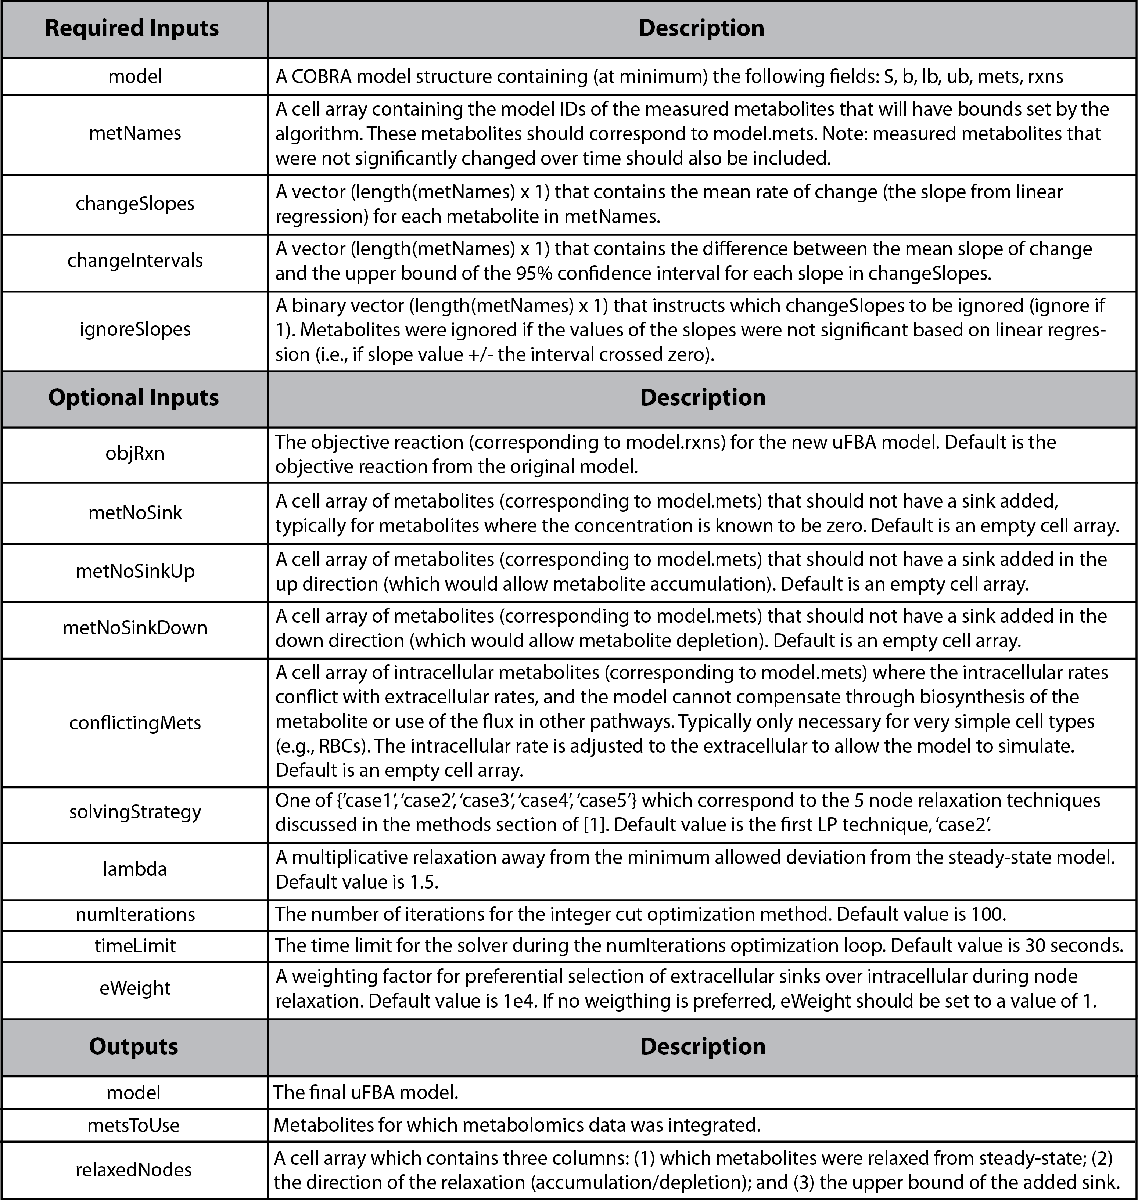

                                       Table 1 | Inputs and outputs of the `buildUFBAmodel` function.

uFBAvariables.metNames = met_IDs;
uFBAvariables.changeSlopes = changeSlopes;
uFBAvariables.changeIntervals = changeIntervals;
uFBAvariables.ignoreSlopes = ignoreSlopes;

uFBAoutput = buildUFBAmodel(model, uFBAvariables);

sink_ascb-L[c]	ascb-L[c] 	<=>	
sink_gthrd[e]	gthrd[e] 	<=>	
sink_urate[e]	urate[e] 	<=>	
sink_10fthf[c]_up	10fthf[c]_G + 10fthf[c]_L 	->	
sink_13dpg[c]_up	13dpg[c]_G + 13dpg[c]_L 	->	
sink_2kmb[c]_up	2kmb[c]_G + 2kmb[c]_L 	->	
sink_35cgmp[c]_up	35cgmp[c]_G + 35cgmp[c]_L 	->	
sink_35cgmp[e]_up	35cgmp[e]_G + 35cgmp[e]_L 	->	
sink_5mdr1p[c]_up	5mdr1p[c]_G + 5mdr1p[c]_L 	->	
sink_5mdru1p[c]_up	5mdru1p[c]_G + 5mdru1p[c]_L 	->	
sink_6pgl[c]_up	6pgl[c]_G + 6pgl[c]_L 	->	
sink_ac[c]_up	ac[c]_G + ac[c]_L 	->	
sink_accoa[c]_up	accoa[c]_G + accoa[c]_L 	->	
sink_adn[c]_up	adn[c]_G + adn[c]_L 	->	
sink_adn[e]_up	adn[e]_G + adn[e]_L 	->	
sink_akg[c]_up	akg[c]_G + akg[c]_L 	->	
sink_akg[e]_up	akg[e]_G + akg[e]_L 	->	
sink_ala-L[e]_up	ala-L[e]_G + ala-L[e]_L 	->	
sink_ametam[c]_up	ametam[c]_G + ametam[c]_L 	->	
sink_arg-L[e]_up	arg-L[e]_G + arg-L[e]_L 	->	
sink_asn-L[e]_up	asn-L[e]_G + asn-L[e]_L 	->	
sink_band[c]_up	band[c]_G + band[c]_L 	->	
sink_bandmt[c]_up	bandmt[c]_G + bandmt[c]_L 	->	
sink_ca2[

The output contains the resulting model (`uFBAoutput.model`):

model_ufba = optimizeCbModel(uFBAoutput.model)

model_ufba =            x: [231×1 double]
           f: 0.2296
           y: [432×1 double]
           w: [231×1 double]
        stat: 1
    origStat: 'OPTIMAL'
      solver: 'gurobi'
        time: 0.0083
           v: [231×1 double]


## References

[1] A Bordbar*, JT Yurkovich*, G Paglia, O Rolfsson, O Sigurjonsson, and BO Palsson. "Elucidating dynamic metabolic physiology through network integration of quantitative time-course metabolomics." *Sci. Rep. *(2017). doi:10.1038/srep46249. (* denotes equal contribution)

[2] A Bordbar, PI Johansson, G Paglia, SJ Harrison, K Wichuk, M Magnusdottir, S Valgeirsdottir, M Gybel-Brask, SR Ostrowski, S Palsson, O Rolfsson, OE Sigurjonsson, MB Hansen, S Gudmundsson, and BO Palsson. "Identified metabolic signature for assessing red blood cell unit quality is associated with endothelial damage markers and clinical outcomes." *Transfusion* (2016). doi:10.1111/trf.13460.

[3] A Bordbar, D McCloskey, DC Zielinski, N Sonnenschein, N Jamshidi, and BO Palsson. "Personalized Whole-Cell Kinetic Models of Metabolism for Discovery in Genomics and Pharmacodynamics." *Cell Systems* (2015). doi:10.1016/j.cels.2015.10.003.